# Properties of the Gaussian Distribution 

## Linear (Affine) transform of a Gaussian

Parameters for Gaussian cluster X

% rng(0); % Fix random seed for reproducibility
n = 100; % Number of points per cluster
mu_X = [10, 10]  % Mean

mu_X =     10    10


sigma_X = [1, 0; 0, 1]  % Covariance

sigma_X =      1     0
     0     1


X = mvnrnd(mu_X, sigma_X, n);

Parameters for Gaussian cluster Y

Y = 2*X + 10*ones(size(X));
mu_Y = mean(Y)

mu_Y =    29.9269   30.2032


sigma_Y = cov(Y)

sigma_Y =     3.8917    0.1275
    0.1275    3.7280


Plot

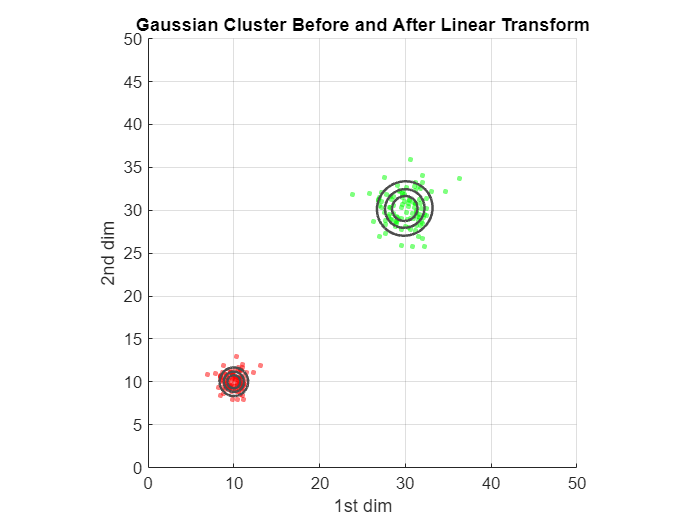

% Plot the figure
figure; hold on; grid on;

% Plot clusters
scatter(X(:,1), X(:,2), 10, 'r', 'filled', 'DisplayName', 'X', 'MarkerFaceAlpha',0.5);
scatter(Y(:,1), Y(:,2), 10, 'g', 'filled', 'DisplayName', 'Y', 'MarkerFaceAlpha',0.5);

% Plot contour function
default_n_contours = 3;
plot_gaussian_contour(mu_X, sigma_X, [.3, .3, .3], default_n_contours);
plot_gaussian_contour(mu_Y, sigma_Y, [.3, .3, .3], default_n_contours);

axis equal
% legend('Location', 'southeast');
xlabel('1st dim');
ylabel('2nd dim');
xlim([0 50])
ylim([0 50])
title('Gaussian Cluster Before and After Linear Transform');
hold off;

## Sum of two Gaussians

Parameters for Gaussian cluster X

% rng(0); % Fix random seed for reproducibility
n = 100; % Number of points per cluster
mu_X = [10, 15]; % Mean
sigma_X = [2, 0; 0, 1]; % Covariance
X = mvnrnd(mu_X, sigma_X, n);

Parameters for Gaussian cluster Y

mu_Y = [16, 20]; % Mean
sigma_Y = [1, 0; 0, 3]; % Covariance
Y = mvnrnd(mu_Y, sigma_Y, n);

Third cluster Z = X + Y

Z = X + Y;
mu_Z = mean(Z);
sigma_Z = cov(Z);

Plot

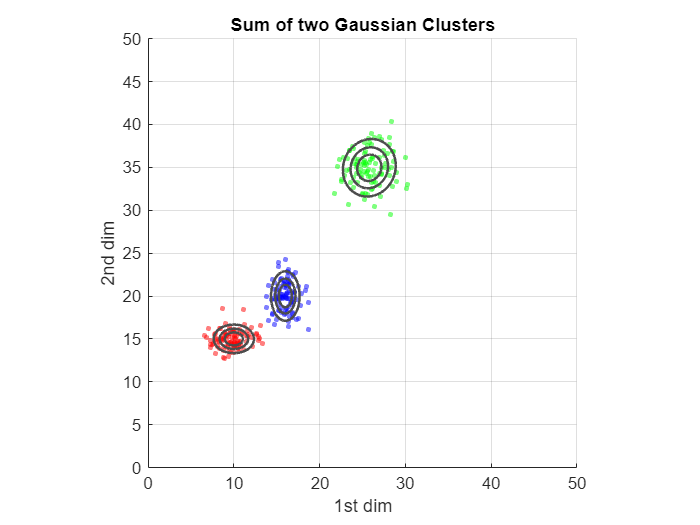

% Plot the figure
figure; hold on; grid on;

% Plot clusters
scatter(X(:,1), X(:,2), 10, 'r', 'filled', 'DisplayName', 'X', 'MarkerFaceAlpha',0.5);
scatter(Y(:,1), Y(:,2), 10, 'b', 'filled', 'DisplayName', 'Y', 'MarkerFaceAlpha',0.5);
scatter(Z(:,1), Z(:,2), 10, 'g', 'filled', 'DisplayName', 'X+Y', 'MarkerFaceAlpha',0.5);   

% Plot contour function
default_n_contours = 3;
plot_gaussian_contour(mu_X, sigma_X, [.3, .3, .3], default_n_contours);
plot_gaussian_contour(mu_Y, sigma_Y, [.3, .3, .3], default_n_contours);
plot_gaussian_contour(mu_Z, sigma_Z, [.3, .3, .3], default_n_contours);

axis equal
% legend('Location', 'southeast');
xlabel('1st dim');
ylabel('2nd dim');
xlim([0 50])
ylim([0 50])
title('Sum of two Gaussian Clusters');
hold off;

## Conditional Gaussian

Parameters for the Gaussian surface

mu = [0, 0]; % Mean
sigma = [1, 0; 0, 1]; % Covariance
r = 5;

% Generate the grid for the Gaussian surface
[x, y] = meshgrid(linspace(-r, r, 400), linspace(-r, r, 400)); % Higher resolution grid
pos = [x(:), y(:)];
z = mvnpdf(pos, mu, sigma);
z = reshape(z, size(x));

Define parameters for the 2-dim subspace (plane)

plane_x = linspace(-r, r, 100); % Range of x-values for the plane
plane_height = 0.2; % Height of the plane above the base

Plot

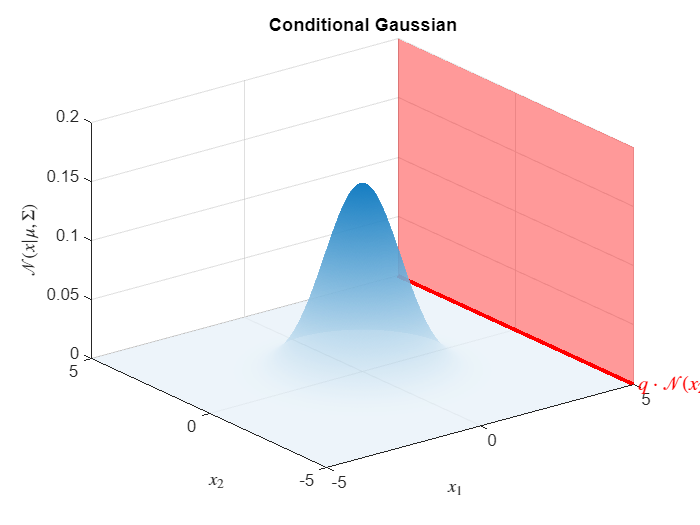

% Create the figure
figure;
axis([-r r -r r 0 0.2]);
grid on;
hold on;

% Plot the Gaussian surface
surf(x, y, z, 'EdgeColor', 'none', 'FaceAlpha', 0.7, 'EdgeColor','none');
colormap('sky');
view(3);
xlabel('$x_1$', 'Interpreter', 'latex');
ylabel('$x_2$', 'Interpreter', 'latex');
zlabel('$\mathcal{N}(x|\mu,\Sigma)$', 'Interpreter', 'latex');
title('Conditional Gaussian');

% Initialize the subspace and the conditional Gaussian curve
plane_handle = fill3([0, 0, 0, 0], [-r, -r, r, r], [0, plane_height, plane_height, 0], 'r', 'FaceAlpha', 0.4,'EdgeColor','none');
intersection_line = plot3(0, 0, 0, 'r', 'LineWidth', 2);

% Add a text annotation for the moving subspace
annotation_handle = text(0, 0, 0, '$q\cdot\mathcal{N}(x_2|x_1,\mu_c,\Sigma_c)$', 'Interpreter', 'latex', 'FontSize', 12, 'Color', 'red');

% Animate the conditional subspace and the Gaussian curve
for i = 1:length(plane_x)
    % Update the subspace position
    new_x = plane_x(i);
    set(plane_handle, 'XData', [new_x, new_x, new_x, new_x]);

    % Compute the subspace within the Gaussian surface
    z_plane = plane_height;
    z_diff = abs(z - z_plane);
    [rows, cols] = find(z_diff < plane_height); % Find intersection points with tighter threshold
    intersection_x = x(sub2ind(size(x), rows, cols));
    intersection_y = y(sub2ind(size(y), rows, cols));
    intersection_z = z(sub2ind(size(z), rows, cols));

    % Further filter points to ensure they align with the moving subspace
    intersection_indices = abs(intersection_x - new_x) < 0.03; % Narrower range
    intersection_x = intersection_x(intersection_indices);
    intersection_y = intersection_y(intersection_indices);
    intersection_z = intersection_z(intersection_indices);

    % Update the conditional Gaussian curve
    set(intersection_line, 'XData', intersection_x, 'YData', intersection_y, 'ZData', intersection_z);

    % Update the annotation position
    set(annotation_handle, 'Position', [new_x, -r-0.1, 0]);

    % Pause for animation effect
    pause(0.05);
end
hold off;

## Helper function: Plot Gaussian distribution contours

function plot_gaussian_contour(mu, sigma, color, n_contours)
    [x, y] = meshgrid(linspace(mu(1) - 4, mu(1) + 4, 100), ...
                      linspace(mu(2) - 4, mu(2) + 4, 100));
    pos = [x(:), y(:)];
    z = mvnpdf(pos, mu, sigma);
    z = reshape(z, size(x));
    [~, h] = contour(x, y, z, n_contours, 'LineColor', color,'DisplayName', '');
    h.LineWidth = 1.5;
end